# Post processing

## Read futek data

% should add out folder to matlab path
fds = fileDatastore('futek_data/experiment_*.txt', 'ReadFcn', @importdata);
fullFileNames = fds.Files;
% [pathstr, name, ext] = fileparts(fullFileNames{1})
numFiles = length(fullFileNames);
% Loop over all files reading them in and plotting them.
futek_data = cell(numFiles,2);
for k = 1 : numFiles

    fprintf('Now reading file %s\n', fullFileNames{k});
    A = import_futek_data(fullFileNames{k});
    if isempty(A) == false
        futek_data{k,1} = A;
        temp = strsplit(fullFileNames{k},"/");
        futek_data{k,2} = temp{end};
    end
end

Now reading file /home/lupasic/Programs/python_ws/tactile-sensor-velostat/src/futek_data/experiment_rep_s1_f.txt
Now reading file /home/lupasic/Programs/python_ws/tactile-sensor-velostat/src/futek_data/experiment_rep_s2_f.txt
Now reading file /home/lupasic/Programs/python_ws/tactile-sensor-velostat/src/futek_data/experiment_rep_s3_f.txt
Now reading file /home/lupasic/Programs/python_ws/tactile-sensor-velostat/src/futek_data/experiment_rolling2_f.txt
Now reading file /home/lupasic/Programs/python_ws/tactile-sensor-velostat/src/futek_data/experiment_rolling_f.txt
Now reading file /home/lupasic/Programs/python_ws/tactile-sensor-velostat/src/futek_data/experiment_same_press_b_f.txt
Now reading file /home/lupasic/Programs/python_ws/tactile-sensor-velostat/src/futek_data/experiment_same_press_mat_b_f.txt
Now reading file /home/lupasic/Programs/python_ws/tactile-sensor-velostat/src/futek_data/experiment_same_press_mat_s_f.txt
Now reading file /home/lupasic/Programs/python_ws/tactile-sensor-ve

## Read velostat data

fds = fileDatastore('velostat_data/experiment_*.txt', 'ReadFcn', @importdata);
fullFileNames = fds.Files;
% [pathstr, name, ext] = fileparts(fullFileNames{1})
numFiles = length(fullFileNames);
% Loop over all files reading them in and plotting them.
velostat_data = cell(numFiles,2);
for k = 1 : numFiles

    fprintf('Now reading file %s\n', fullFileNames{k});
    A = import_velostat_data(fullFileNames{k});
    if isempty(A) == false
        velostat_data{k,1} = A;
        temp = strsplit(fullFileNames{k},"/");
        velostat_data{k,2} = temp{end};
    end
end

Now reading file /home/lupasic/Programs/python_ws/tactile-sensor-velostat/src/velostat_data/experiment_.txt
Now reading file /home/lupasic/Programs/python_ws/tactile-sensor-velostat/src/velostat_data/experiment_rep_s1_v.txt
Now reading file /home/lupasic/Programs/python_ws/tactile-sensor-velostat/src/velostat_data/experiment_rep_s2_v.txt
Now reading file /home/lupasic/Programs/python_ws/tactile-sensor-velostat/src/velostat_data/experiment_rep_s3_v.txt
Now reading file /home/lupasic/Programs/python_ws/tactile-sensor-velostat/src/velostat_data/experiment_rolling2_v.txt
Now reading file /home/lupasic/Programs/python_ws/tactile-sensor-velostat/src/velostat_data/experiment_rolling_v.txt
Now reading file /home/lupasic/Programs/python_ws/tactile-sensor-velostat/src/velostat_data/experiment_same_press_b_v.txt
Now reading file /home/lupasic/Programs/python_ws/tactile-sensor-velostat/src/velostat_data/experiment_same_press_mat_b_v.txt
Now reading file /home/lupasic/Programs/python_ws/tactile-sen

## Take needed data

%same order
needed_futek_num=[1 2 3]';
needed_velostat_num = [2 3 4]';
futek_data = futek_data(needed_futek_num,:);
velostat_data = velostat_data(needed_velostat_num,:);

% receive a mat of values from futek, 1 file
% cur_mat = cell2mat(velostat_data{1,1}(:,1));

## Read data from futek

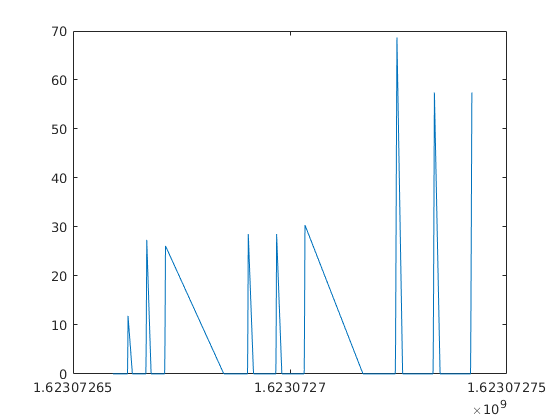

plot(cell2mat(experimenttestsensor3f(:,2)),cell2mat(experimenttestsensor3f(:,1)),'DisplayName','ans')

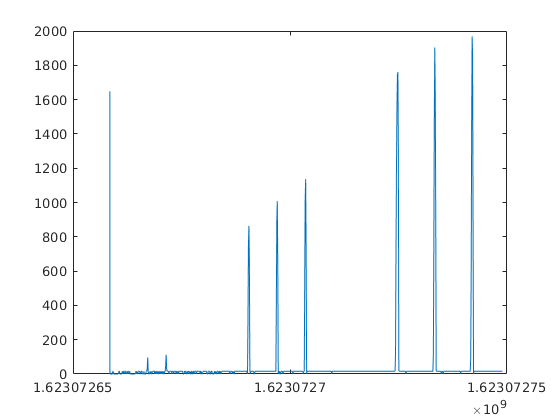

figure
plot(cell2mat(experimenttestsensor3v(:,2)),cell2mat(experimenttestsensor3v(:,1)),'DisplayName','ans')

a =     16
     0
     0
     0
     0
     0
     0
     0
     0
     0


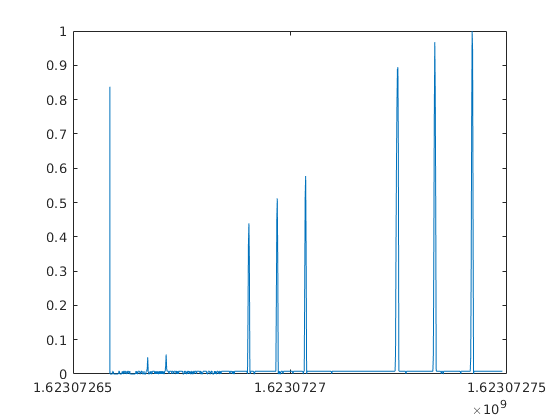

plot(cell2mat(experimenttestsensor3v(:,2)),norm_data(cell2mat(experimenttestsensor3v(:,1))),'DisplayName','ans')

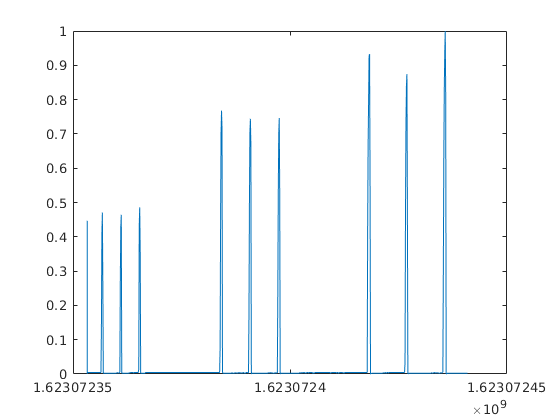

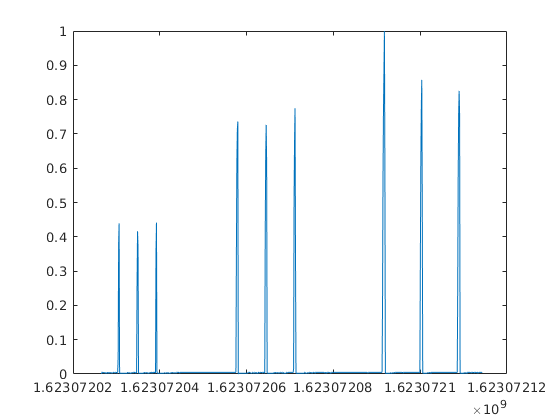

plot(cell2mat(experimenttestsensor2v(:,2)),norm_data(cell2mat(experimenttestsensor2v(:,1))),'DisplayName','ans')
plot(cell2mat(experimenttestsensorv(:,2)),norm_data(cell2mat(experimenttestsensorv(:,1))),'DisplayName','ans')
